record = [];
starting_record = 4;
data_path = "data/S001/S001";
includeAR = true;
for i=0:2
    record = [record string(num2str(starting_record+i*4, '%02d'))];
end

t1s = cell(0);
t2s = cell(0);

for i=1:numel(record)
    recName = strcat(data_path, "R", record(i), ".edf");
    recName = convertStringsToChars(recName);
    disp(recName);

    [eeg, fs, ~] = rdsamp(recName, 1:64);

    [~, T1, T2] = getIntervals(recName, 'event', fs, size(eeg,1));

    eeg = eeg.';

    for j = 1:size(T1, 1)
        segment = eeg(:, T1(j, 1):T1(j, 2));
        t1s{end + 1} = segment;
    end

    for j = 1:size(T2, 1)
        segment = eeg(:, T2(j, 1):T2(j, 2));
        t2s{end + 1} = segment;
    end

end

data/S001/S001R04.edf
data/S001/S001R08.edf
data/S001/S001R12.edf



featF = 'featureVectors.txt';
clasF = 'referenceClass.txt';
fvf = fopen(featF, "wt");
rcf = fopen(clasF, "wt");

f = [0 8 8 13 13 fs/2]/(fs/2);
a = [0 0 1 1 0 0];
n = 35;
b = firls(n, f, a);

[W] = f_CSP(cell2mat(t1s(1)), cell2mat(t2s(1)));
t1s(1) = [];
t2s(1) = [];

lvt1 = cell(size(t1s));
lvt2 = cell(size(t2s));

p = 2;

for i = 1:numel(t1s)
    cst = W * cell2mat(t1s(i));
    cse = [cst(1, :).', cst(size(cst, 1), :).'].';
    csf = filter(b, 1, cse);

    if includeAR
        AR_features = [];
        AR_order = min(p, size(csf, 1) - 1);
        for j = 1:size(csf, 2)
            AR_coeffs = arburg(csf(:, j), AR_order);
            AR_features = [AR_features; AR_coeffs'];
        end
        lvt1{i} = [log(var(csf(1, :))), log(var(csf(2, :))), AR_features(:)'];
    else
        lvt1{i} = [log(var(csf(1, :))), log(var(csf(2, :)))];
    end
end

for i = 1:numel(t2s)
    cst = W * cell2mat(t2s(i));
    cse = [cst(1, :).', cst(size(cst, 1), :).'].';
    csf = filter(b, 1, cse);

    if includeAR
        AR_features = [];
        AR_order = min(p, size(csf, 1) - 1);
        for j = 1:size(csf, 2)
            AR_coeffs = arburg(csf(:, j), AR_order);
            AR_features = [AR_features; AR_coeffs'];
        end
        lvt2{i} = [log(var(csf(1, :))), log(var(csf(2, :))), AR_features(:)'];
    else
        lvt2{i} = [log(var(csf(1, :))), log(var(csf(2, :)))];
    end
end

for i = 1:numel(lvt1) - 1
    fprintf(fvf, '%.8f %.8f', lvt1{i}(1), lvt1{i}(2));
    for k = 3:numel(lvt1{i})
        fprintf(fvf, ' %.8f', lvt1{i}(k));
    end
    fprintf(fvf, '\n');
    fprintf(rcf, 'T1\n');
end

for i = 1:numel(lvt2) - 1
    fprintf(fvf, '%.8f %.8f', lvt2{i}(1), lvt2{i}(2));
    for k = 3:numel(lvt2{i})
        fprintf(fvf, ' %.8f', lvt2{i}(k));
    end
    fprintf(fvf, '\n');
    fprintf(rcf, 'T2\n');
end

fclose(fvf);
fclose(rcf);

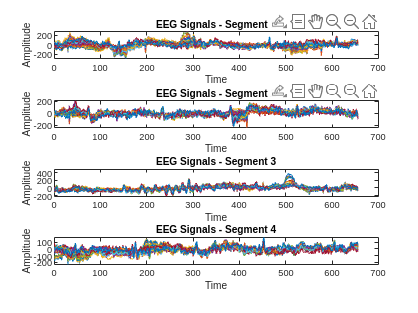

num_segments = min(numel(t1s), 4); 

figure;
for i = 1:num_segments
    subplot(num_segments, 1, i);
    plot(t1s{i}');
    title(['EEG Signals - Segment ', num2str(i)]);
    xlabel('Time');
    ylabel('Amplitude');
end

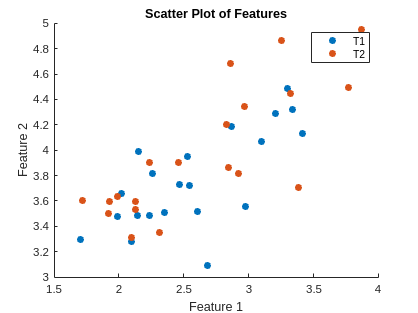

data = load('featureVectors.txt');

feature1 = data(:, 1);
feature2 = data(:, 2);
classLabels = importdata('referenceClass.txt');

T1_indices = find(strcmp(classLabels, 'T1'));
T2_indices = find(strcmp(classLabels, 'T2'));

figure;
scatter(feature1(T1_indices), feature2(T1_indices), 'filled', 'DisplayName', 'T1');
hold on;
scatter(feature1(T2_indices), feature2(T2_indices), 'filled', 'DisplayName', 'T2');
title('Scatter Plot of Features');
xlabel('Feature 1');
ylabel('Feature 2');
legend('show');

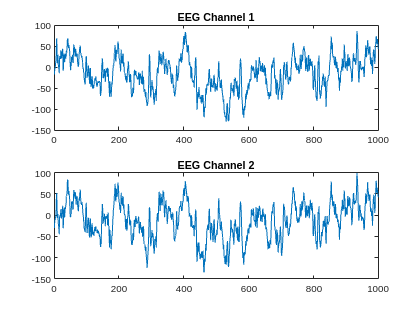

segment_to_plot = eeg(:, 1:1000); 

figure;
subplot(2,1,1);
plot(segment_to_plot(1, :)); 
title('EEG Channel 1');

subplot(2,1,2);
plot(segment_to_plot(2, :)); 
title('EEG Channel 2');

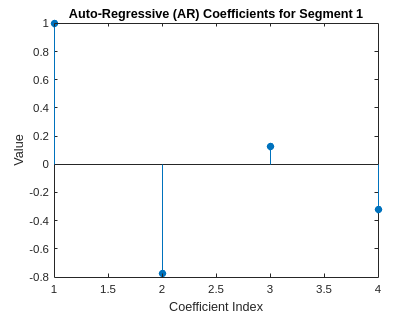

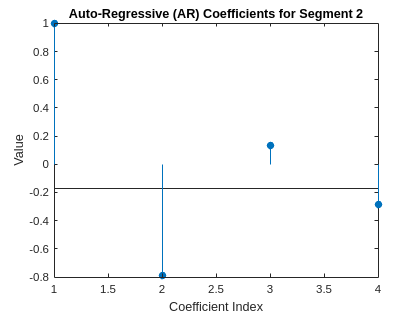

min_AR_order = 2;
num_segments = size(csf, 1);

for segment_index = 1:num_segments
    segment = csf(segment_index, :);
    AR_coeffs = arburg(segment, AR_order);
    figure;
    stem(1:length(AR_coeffs), AR_coeffs, 'filled');
    xlabel('Coefficient Index');
    ylabel('Value');
    title(['Auto-Regressive (AR) Coefficients for Segment ', num2str(segment_index)]);
end

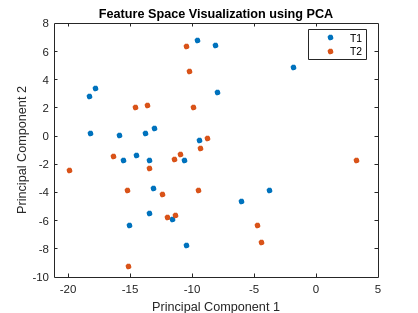

lvt1_numeric = cell2mat(lvt1');
lvt2_numeric = cell2mat(lvt2');

% trim to match dimensions
if size(lvt1_numeric, 2) > size(lvt2_numeric, 2)
    lvt1_numeric = lvt1_numeric(:, 1:size(lvt2_numeric, 2));
elseif size(lvt1_numeric, 2) < size(lvt2_numeric, 2)
    lvt2_numeric = lvt2_numeric(:, 1:size(lvt1_numeric, 2));
end

all_features = [lvt1_numeric; lvt2_numeric];
labels = [repmat("T1", size(lvt1_numeric, 1), 1); repmat("T2", size(lvt2_numeric, 1), 1)];

coeff = pca(all_features); 
reduced_features = all_features * coeff(:, 1:2);

figure;
gscatter(reduced_features(:, 1), reduced_features(:, 2), labels);
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('Feature Space Visualization using PCA');
legend('T1', 'T2');

Size: 41x1314; EVENT: T1; NON-EVENT: T2
LDA
   All records-Test   TP= 19 FN=  2; FP=  1 TN= 19; Se:  90.48 Sp:  95.00 CA:  92.68 AUC:  94.52
   All records-Learn  TP= 19 FN=  2; FP=  1 TN= 19; Se:  90.48 Sp:  95.00 CA:  92.68 AUC:  94.52
   20% holdout-Test  Single  TP=  3 FN=  1; FP=  3 TN=  1; Se:  75.00 Sp:  25.00 CA:  50.00 AUC:  43.75
   20% holdout-Learn Single  TP=  3 FN=  1; FP=  3 TN=  1; Se:  75.00 Sp:  25.00 CA:  50.00 AUC:  92.28
     20% holdout-Test  Nrep  TP=  3 FN=  1; FP=  2 TN=  2; Se:  75.00 Sp:  50.00 CA:  62.50 AUC:  57.25
     20% holdout-Learn Nrep  TP=  3 FN=  1; FP=  2 TN=  2; Se:  75.00 Sp:  50.00 CA:  62.50 AUC:  90.73
   Cross-valid-Test  Single  TP= 15 FN=  6; FP= 11 TN=  9; Se:  71.43 Sp:  45.00 CA:  58.54 AUC:  53.33
   Cross-valid-Learn Single  TP= 15 FN=  6; FP= 11 TN=  9; Se:  71.43 Sp:  45.00 CA:  58.54 AUC:  92.51


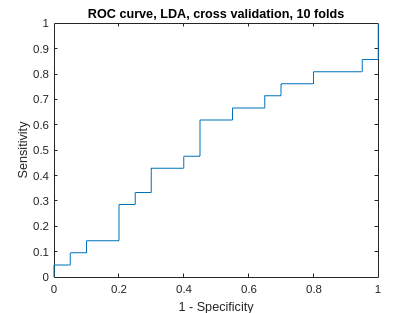

     Cross-valid-Test  Nrep  TP= 12 FN=  9; FP= 10 TN= 10; Se:  57.14 Sp:  50.00 CA:  53.66 AUC:  54.13
     Cross-valid-Learn Nrep  TP= 12 FN=  9; FP= 10 TN= 10; Se:  57.14 Sp:  50.00 CA:  53.66 AUC:  92.49
   Leave one o-Test   TP= 12 FN=  9; FP=  9 TN= 11; Se:  57.14 Sp:  55.00 CA:  56.10 AUC:  54.76
   Leave one o-Learn  TP= 12 FN=  9; FP=  9 TN= 11; Se:  57.14 Sp:  55.00 CA:  56.10 AUC:  94.01


doClassification('featureVectors.txt', 'referenceClass.txt', {1, 0}, 10, 50, 0)